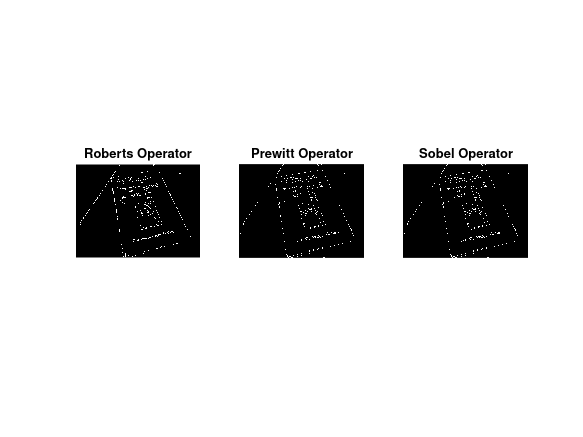

% 1a
imdata1 = imread('book.jpg');
imdata2 = imread('shelf.jpg');
imdata1 = rgb2gray(imdata1);
imdata2 = rgb2gray(imdata2);

roberts_edges1 = edge(imdata1, 'Roberts');
prew_edges1 = edge(imdata1, 'Prewitt');
sob_edges1 = edge(imdata1, 'Sobel');

roberts_edges2 = edge(imdata2, 'Roberts');
prew_edges2 = edge(imdata2, 'Prewitt');
sob_edges2 = edge(imdata2, 'Sobel');

figure;
subplot(1,3,1);
imshow(roberts_edges1);
title('Roberts Operator');

subplot(1,3,2);
imshow(prew_edges1);
title('Prewitt Operator');

subplot(1,3,3);
imshow(sob_edges1);
title('Sobel Operator');

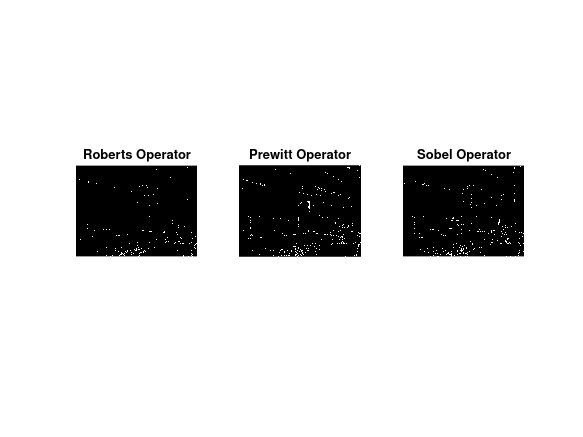


figure;
subplot(1,3,1);
imshow(roberts_edges2);
title('Roberts Operator');

subplot(1,3,2);
imshow(prew_edges2);
title('Prewitt Operator');

subplot(1,3,3);
imshow(sob_edges2);
title('Sobel Operator');

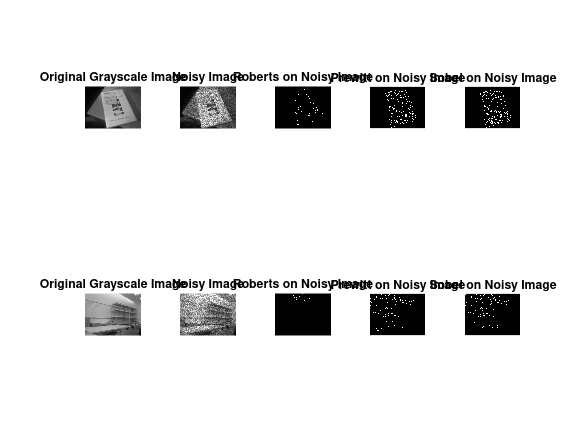

% 1b
noise1 = imnoise(imdata1, 'speckle', 0.05);
noise2 = imnoise(imdata2, 'speckle', 0.05);

roberts_noise1 = edge(noise1, 'Roberts');
prew_noise1 = edge(noise1, 'Prewitt');
sob_noise1 = edge(noise1, 'Sobel');

roberts_noise2 = edge(noise2, 'Roberts');
prew_noise2 = edge(noise2, 'Prewitt');
sob_noise2 = edge(noise2, 'Sobel');

figure;
subplot(2,5,1);
imshow(imdata1);
title('Original Grayscale Image');

subplot(2,5,2);
imshow(noise1);
title('Noisy Image');

subplot(2,5,3);
imshow(roberts_noise1);
title('Roberts on Noisy Image');

subplot(2,5,4);
imshow(prew_noise1);
title('Prewitt on Noisy Image');

subplot(2,5,5);
imshow(sob_noise1);
title('Sobel on Noisy Image');

subplot(2,5,6);
imshow(imdata2);
title('Original Grayscale Image');

subplot(2,5,7);
imshow(noise2);
title('Noisy Image');

subplot(2,5,8);
imshow(roberts_noise2);
title('Roberts on Noisy Image');

subplot(2,5,9);
imshow(prew_noise2);
title('Prewitt on Noisy Image');

subplot(2,5,10);
imshow(sob_noise2);
title('Sobel on Noisy Image');

1c

All of the operators seemed to perform equally well in the edge detection of the original image, particularly on the book image. Each operator had showed the distinguished edges of the table and book, but Roberts from my perspective seemed to have a clearer detection of the edges on the actual cover. Sobel, on the other hand, seemed to have slightly messier edge detection on the book cover.

I added salt and pepper noise to the images, and all images operators seemed to struggle immensely with edge detection. In each of the operators, all the 'edges' were scattered and nothing stood out that could potentially be an edge. When I switched to speckle noise, the operators seemed to start actually detecting. For the book image, the prewitt and sobel operators did the best in distinguishing the shape of the book, while roberts could detect some corners but not the full object. All three operators struggled with the shelf image, but both prewitt and sobel could somewhat distinguish that there was a shelf, as there is a significant/notable block where the shelf should be. 

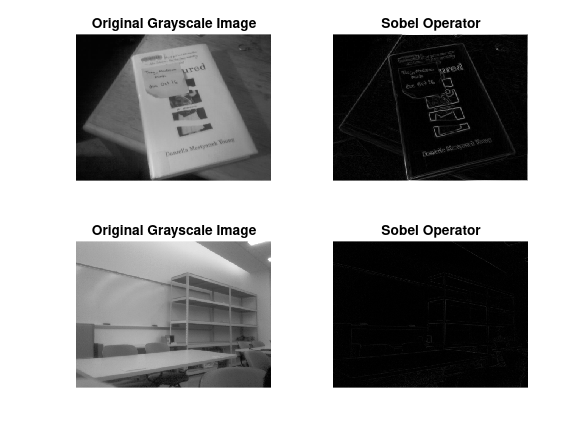

% 2a
Gx = [-1 0 1; -2 0 2; -1 0 1];  % horizontal kernel
Gy = [1 2 1;  0 0 0; -1 -2 -1]; % vertical kernel

% image1
sobel_x1 = imfilter(double(imdata1), Gx);
sobel_y1 = imfilter(double(imdata1), Gy);

gradient_mag1 = sqrt(sobel_x1.^2 + sobel_y1.^2); % combine

% image2
sobel_x2 = imfilter(double(imdata2), Gx);
sobel_y2 = imfilter(double(imdata2), Gy);

gradient_mag2 = sqrt(sobel_x2.^2 + sobel_y2.^2);

figure;
subplot(2,2,1);
imshow(imdata1);
title('Original Grayscale Image');

subplot(2,2,2);
imshow(gradient_mag1, []);
title('Sobel Operator');

subplot(2,2,3);
imshow(imdata2);
title('Original Grayscale Image');

subplot(2,2,4);
imshow(gradient_mag2, []);
title('Sobel Operator');

% source: https://homepages.inf.ed.ac.uk/rbf/HIPR2/sobel.htm


2b

For the book image, my implementation of the sobel operator far outperformed the inbuilt functions. Though both implementations could detect the edges, my implementation was able to detect more fine lines within the book cover, and to some extent the words written as well. However for the shelf image, it underperformed. Where the built ins were able to at least somewhat outline the shape of the shelf, my implementation did not even have lines detecting any edges. 